# 做2022年VaR的预测

方法对比：Historical simulation, mean-variance

We use forecast volatilites to estimate VaR.

%% load data
clear,clc
database=load("VolFcst_normal_SP500_size750_20220707.mat");
D=readtable("SP500_0608.xlsx");
forecast_index=D.Date>=datetime(2022,1,1);
SaveVaRNameSuffix='SP500_20220718';
SaveTxtName='VaR_SP500_2020220718.txt';
% Model_Name={'Historical simulation','Variance-covariance','GARCH','CPGARCH','CPGARCHiteration',...
%     'GJR','CPGJR','CPGJRiteration','RSGARCH','CPRSGARCH','CPRSGARCHiteration',...
%     'HAR','CPHAR','CPHARiteration','Variance-covariance','GARCH','CPGARCH','CPGARCHiteration',...
%     'GJR','CPGJR','CPGJRiteration','RSGARCH','CPRSGARCH','CPRSGARCHiteration',...
%     'HAR','CPHAR','CPHARiteration'};
CL_Name={'99.7\5%','99.5\%','99\%','97.5\%','95\%','92.5\%','90\%'};

Preparation

logRet=D.Return(forecast_index);
TimeLine=D.Date(forecast_index);
T=length(logRet); % forecast window
ConfidenceLevel=[0.25 0.5 1 2.5 5 7.5 10]*0.01;
FigureVaRIndex=[3,5,7];% use FigureVaRIndex of ConfidenceLevel to figure VaR


% Writing header
ftxt=fopen(SaveTxtName,'a+');
n_row = size(T,1);
n_col = size(CL_Name,2);
col_spec = [];
for c = 1:n_col, col_spec = [col_spec 'l']; end
col_names = strjoin(CL_Name, ' & ');
col_spec = ['l' col_spec];
col_names = ['& ' col_names];
fprintf(ftxt,'\\begin{tabular}{%s}\n', col_spec);
fprintf(ftxt,'%s \\\\ \n', col_names);
fprintf(ftxt,'\\hline \n');
fclose(ftxt);

% Writing middle

## 历史模拟法

hVaR = zeros(size(logRet,1),length(ConfidenceLevel)); % historical simulation
for i = 1 : T
    historic_return = D.Return(find(forecast_index,1)+i-251:find(forecast_index,1)+i-2);
    %历史模拟法
    confidence = prctile(historic_return, ConfidenceLevel*100);
    hVaR(i, :) = confidence;
end

% ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'历史模拟法. \n');fclose(ftxt);
TableOutput=tableVaRPredict(hVaR,logRet,ConfidenceLevel)%历史模拟法

TableOutput = 4×7 table
                        CL0.0025    CL0.005    CL0.01     CL0.025    CL0.05     CL0.075    CL0.1
                        ________    _______    _______    _______    _______    _______    _____

    Confidence level     0.0025       0.005       0.01      0.025       0.05      0.075      0.1
    Failures                  5           6          8         10         16         21       28
    Kupiec Test           21.09       19.59      20.38      13.98      17.56      19.62    27.38
    Significance              1     0.99999    0.99999    0.99982    0.99997    0.99999        1


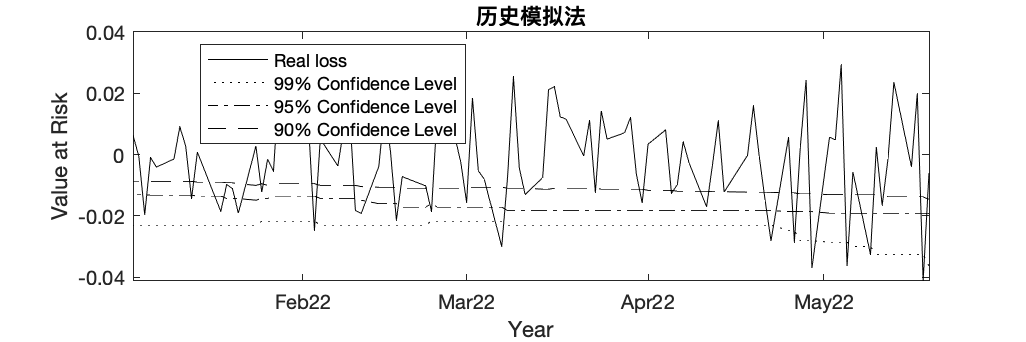

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,'Historical simulation &');
line2latex(TableOutput(3,:),ftxt)
fclose(ftxt);
figureVaR(hVaR(:,FigureVaRIndex),logRet,TimeLine);
title('历史模拟法')

## Variance-covariance normal 分布

pVaR_normal = zeros(size(logRet,1),length(ConfidenceLevel)); % variance-covariance normal distribution
for i = 1 : T
    historic_return = D.Return(find(forecast_index,1)+i-251:find(forecast_index,1)+i-2);
    % innovation normal distributed
    pVaR_normal(i, :) = norminv(ConfidenceLevel,mean(historic_return),std(historic_return));    
end
TableOutput=tableVaRPredict(pVaR_normal,logRet,ConfidenceLevel)% normal distribution

TableOutput = 4×7 table
                        CL0.0025    CL0.005    CL0.01    CL0.025    CL0.05    CL0.075    CL0.1
                        ________    _______    ______    _______    ______    _______    _____

    Confidence level     0.0025      0.005      0.01      0.025      0.05      0.075       0.1
    Failures                  8          8        12         15        19         23        27
    Kupiec Test           41.23      30.58     39.87      31.56     26.22      24.82     24.81
    Significance              1          1         1          1         1          1         1


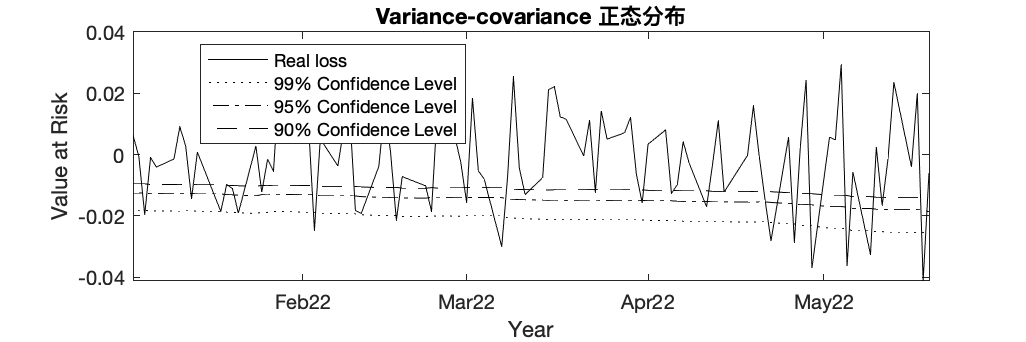

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,'Variance-covariance &');
line2latex(TableOutput(3,:),ftxt)
fclose(ftxt);
figureVaR(pVaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title('Variance-covariance 正态分布')

## GARCH normal VaR

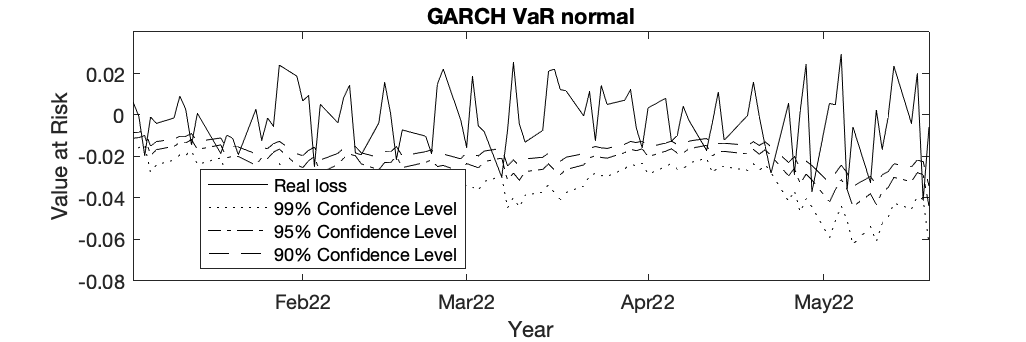

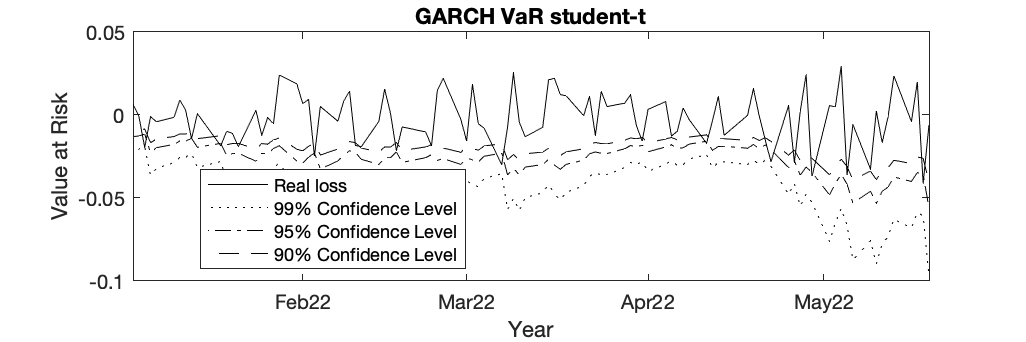

Model_Name='GARCH';
vf=database.vf_GARCH;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_normal(3,:),ftxt)
fclose(ftxt);

## CPGARCH normal VaR

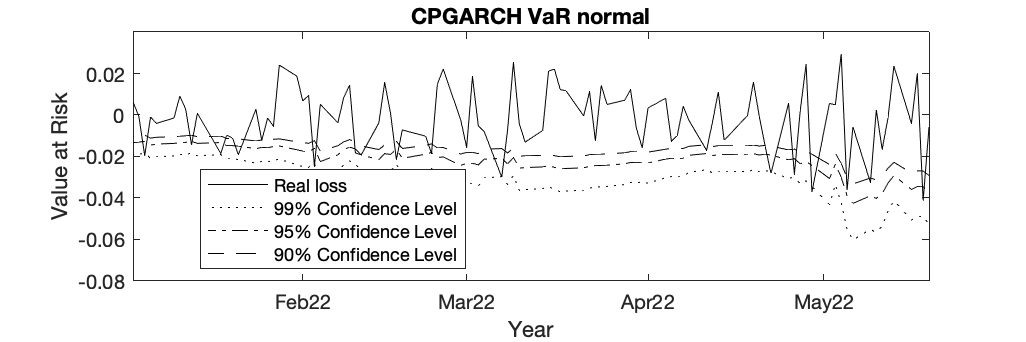

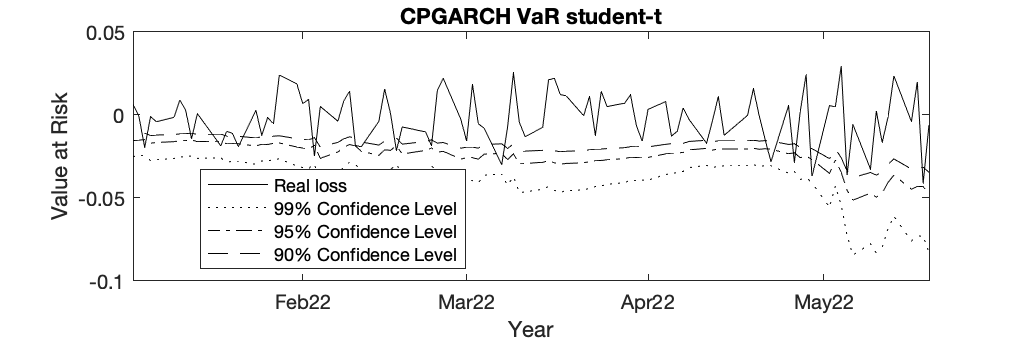

Model_Name='CPGARCH';
vf=database.vf_CPGARCH;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_normal(3,:),ftxt)
fclose(ftxt);

## CPGARCHiteration normal VaR

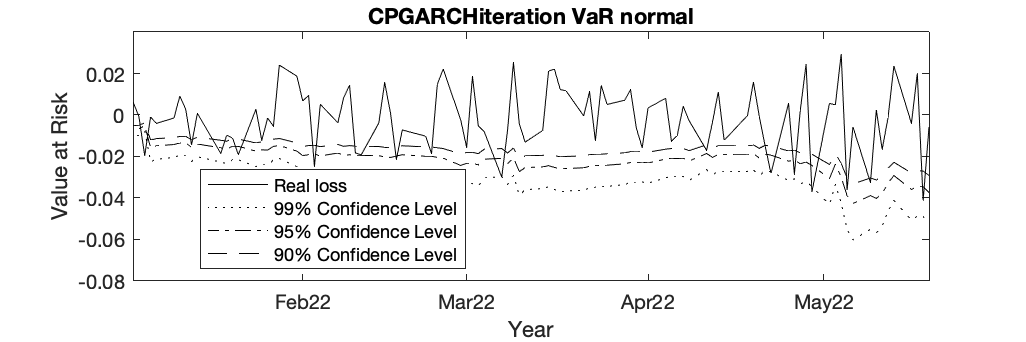

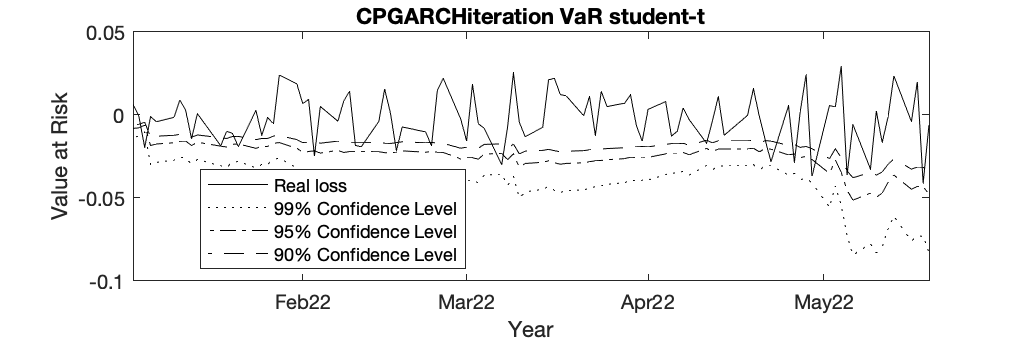

Model_Name='CPGARCHiteration';
vf=database.vf_CPGARCHiteration;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_normal(3,:),ftxt)
fclose(ftxt);

## GJR normal VaR

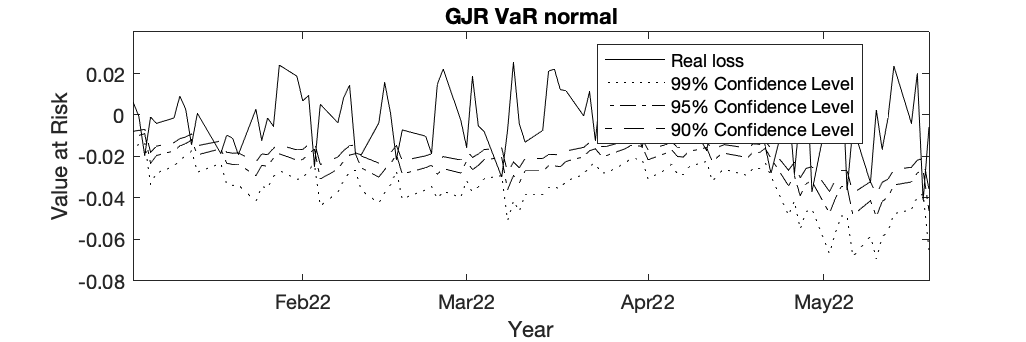

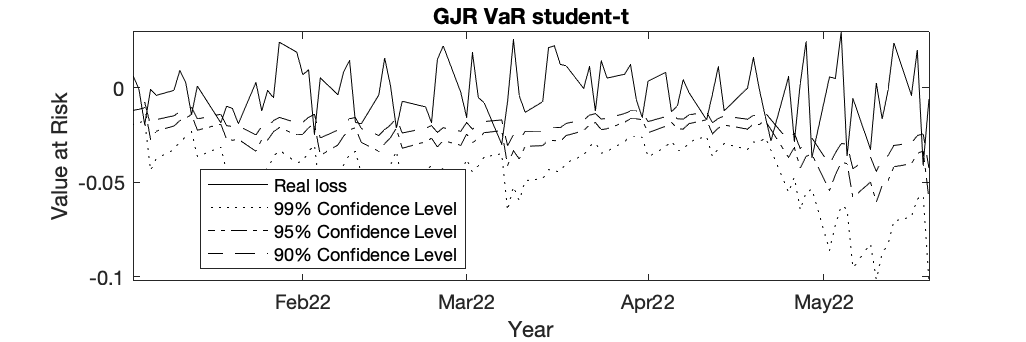

Model_Name='GJR';
vf=database.vf_GJR;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_normal(3,:),ftxt)
fclose(ftxt);

## CPGJR normal VaR

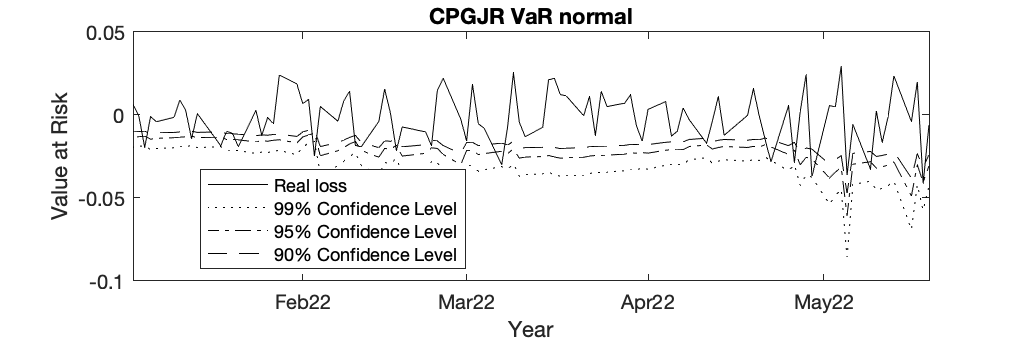

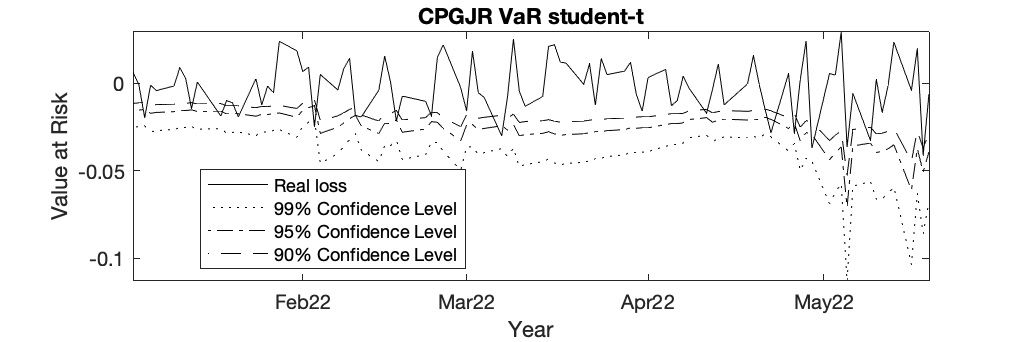

Model_Name='CPGJR';
vf=database.vf_CPGJR;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_normal(3,:),ftxt)
fclose(ftxt);

## CPGJRiteration normal VaR

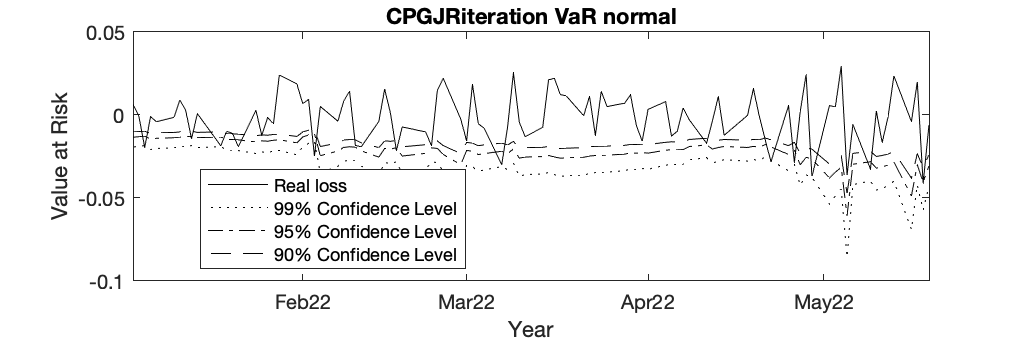

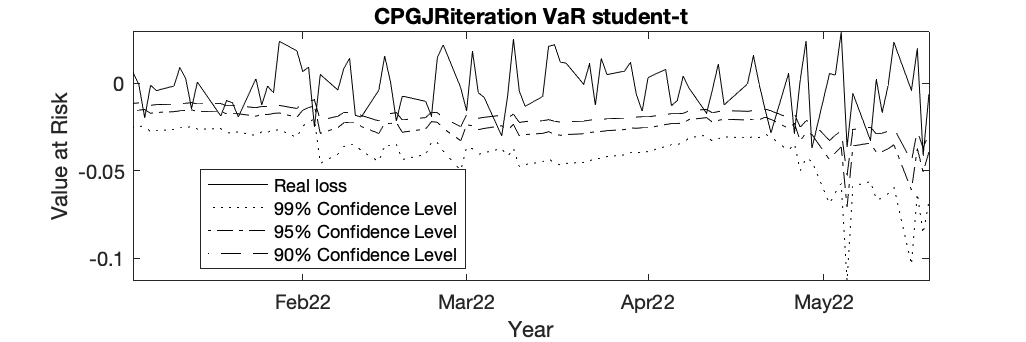

Model_Name='CPGJRiteration';
vf=database.vf_CPGJRiteration;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_normal(3,:),ftxt)
fclose(ftxt);

## RSGARCH normal VaR

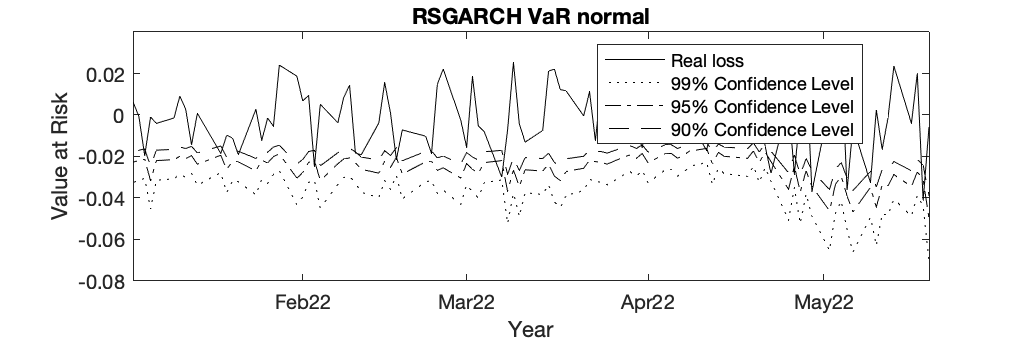

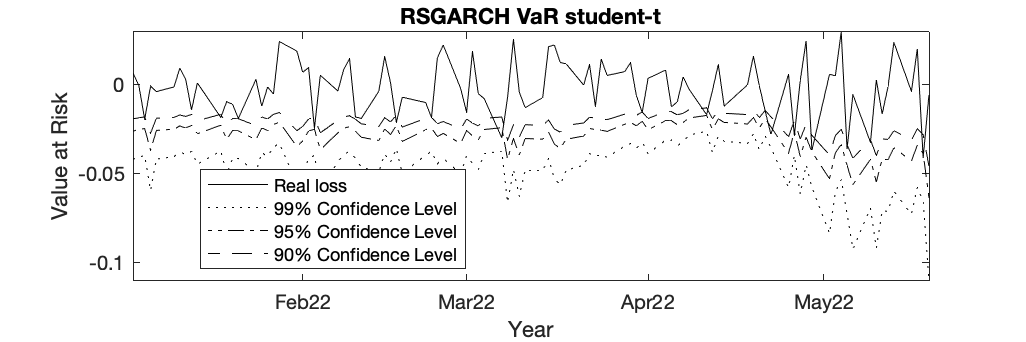

Model_Name='RSGARCH';
vf=database.vf_RSGARCH;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_normal(3,:),ftxt)
fclose(ftxt);

## CPRSGARCH normal VaR

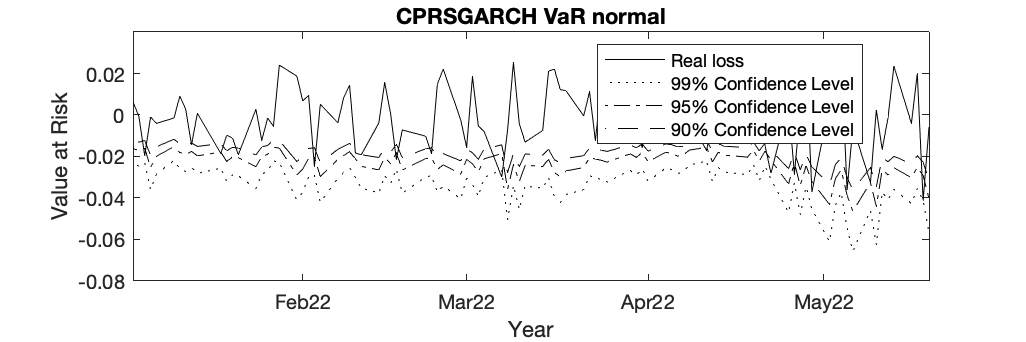

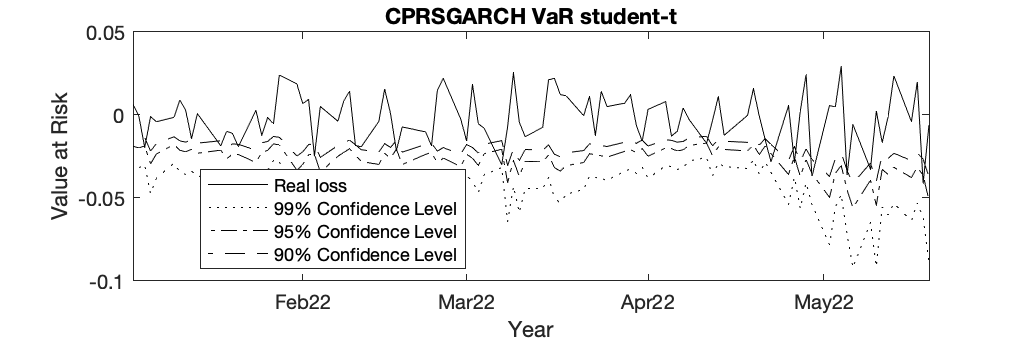

Model_Name='CPRSGARCH';
vf=database.vf_CPRSGARCH;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_normal(3,:),ftxt)
fclose(ftxt);

## CPRSGARCHiteration normal VaR

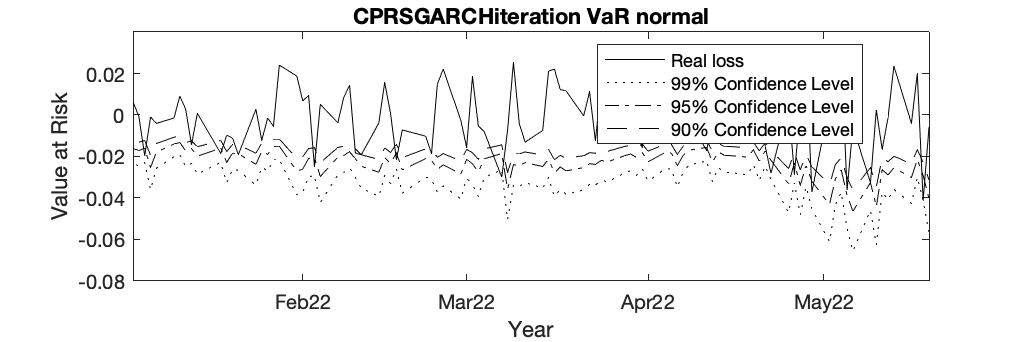

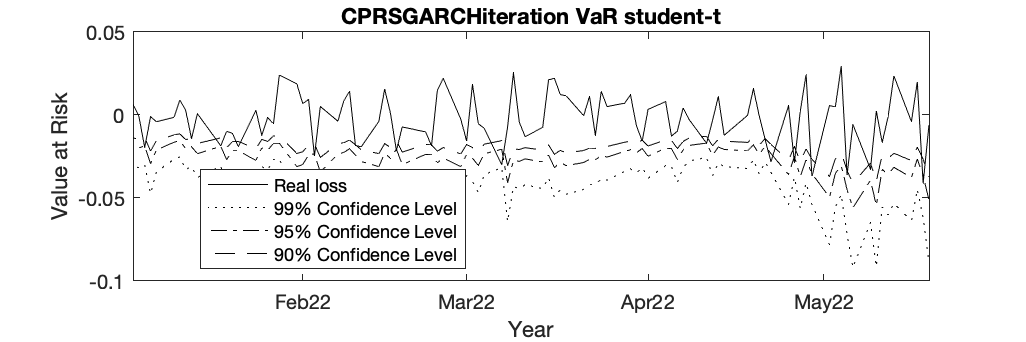

Model_Name='CPRSGARCHiteration';
vf=database.vf_CPRSGARCHiteration;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_normal(3,:),ftxt)
fclose(ftxt);

## HAR normal VaR

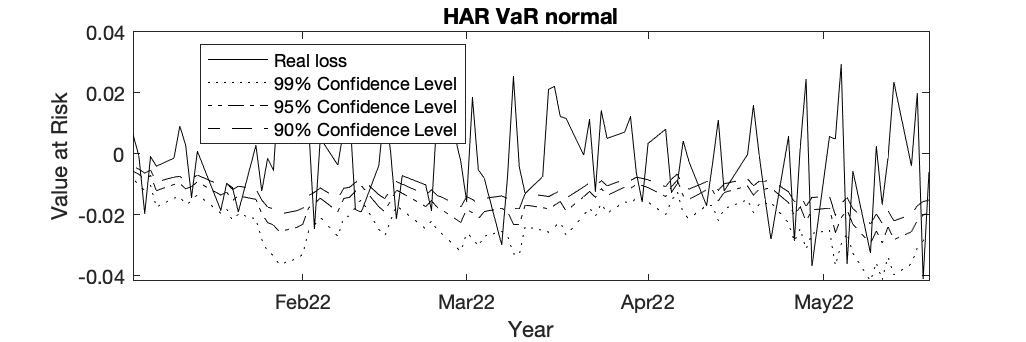

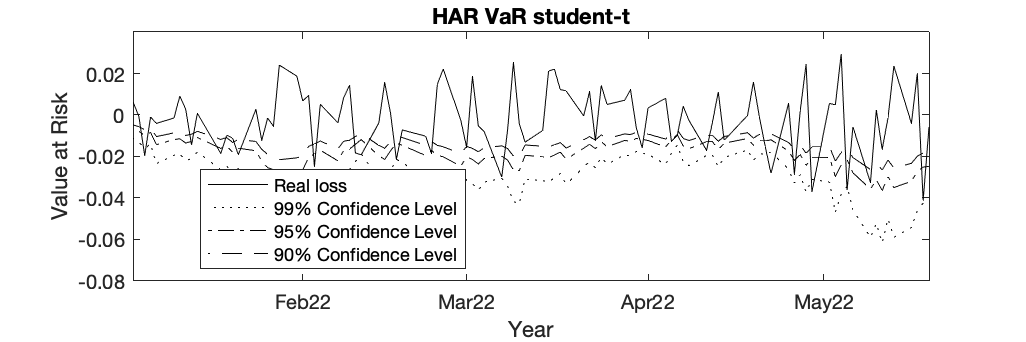

Model_Name='HAR';
vf=database.vf_HAR;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_normal(3,:),ftxt)
fclose(ftxt);

## CPHAR normal VaR

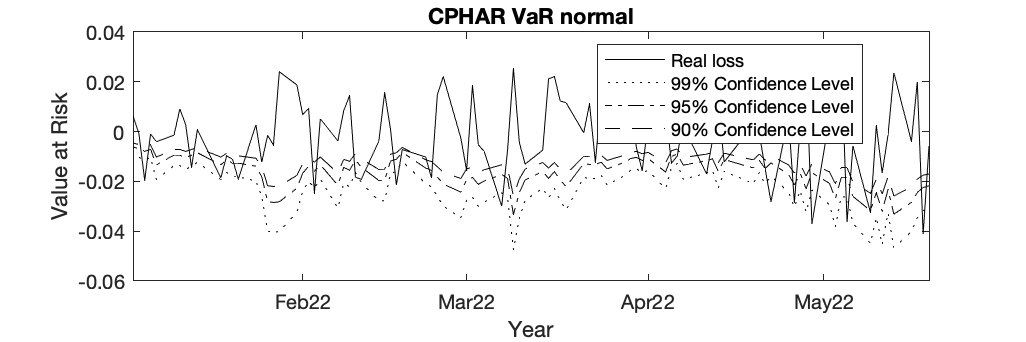

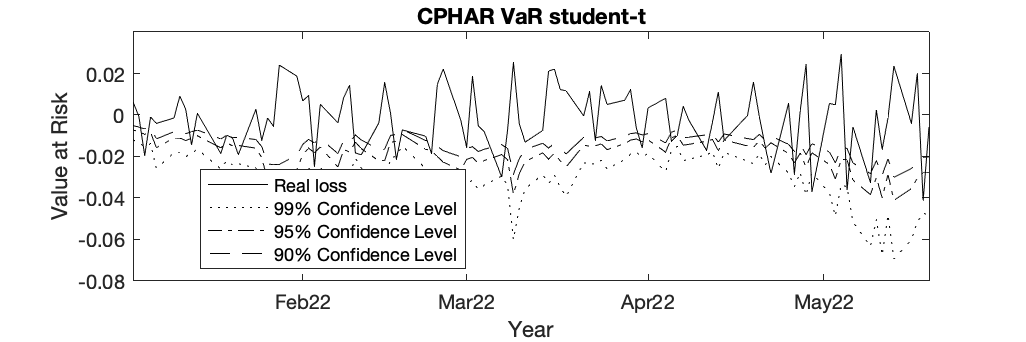

Model_Name='CPHAR';
vf=database.vf_CPHAR;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_normal(3,:),ftxt)
fclose(ftxt);

## CPHARiteration normal VaR

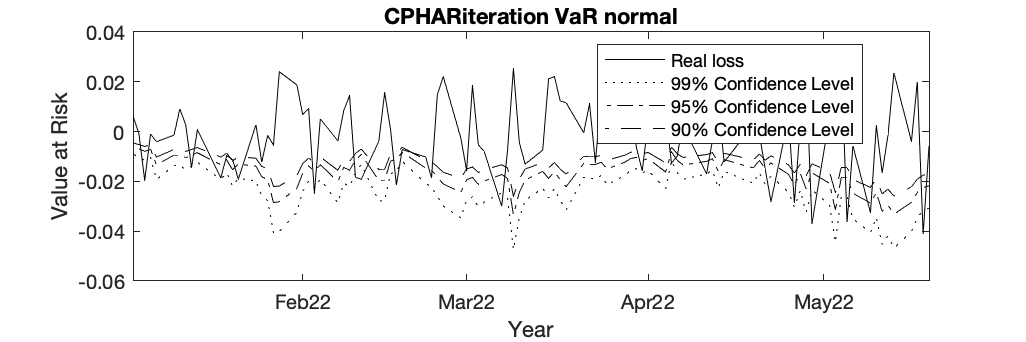

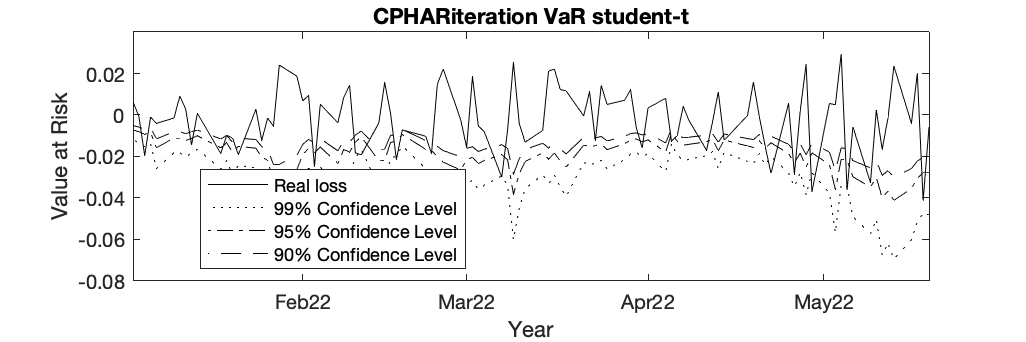

Model_Name='CPHARiteration';
vf=database.vf_CPHARiteration;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_normal(3,:),ftxt)
fclose(ftxt);

## Variance-covariance t分布

pVaR_t = zeros(size(logRet,1),length(ConfidenceLevel));% variance-covariance t distribution
for i = 1 : T
    historic_return = D.Return(find(forecast_index,1)+i-251:find(forecast_index,1)+i-2);
    % innovation student-t distributed
    fit_data=fitdist(historic_return,"tLocationScale");
    pVaR_t(i, :) = tinv(ConfidenceLevel,fit_data.nu)*fit_data.sigma+fit_data.mu;
end
TableOutput=tableVaRPredict(pVaR_t,logRet,ConfidenceLevel)% student-t distribution

TableOutput = 4×7 table
                        CL0.0025    CL0.005    CL0.01    CL0.025    CL0.05    CL0.075    CL0.1
                        ________    _______    ______    _______    ______    _______    _____

    Confidence level     0.0025      0.005      0.01      0.025      0.05      0.075       0.1
    Failures                  3          7         9         15        19         26        28
    Kupiec Test            9.71      24.93     24.91      31.56     26.22      33.46     27.38
    Significance        0.99817          1         1          1         1          1         1


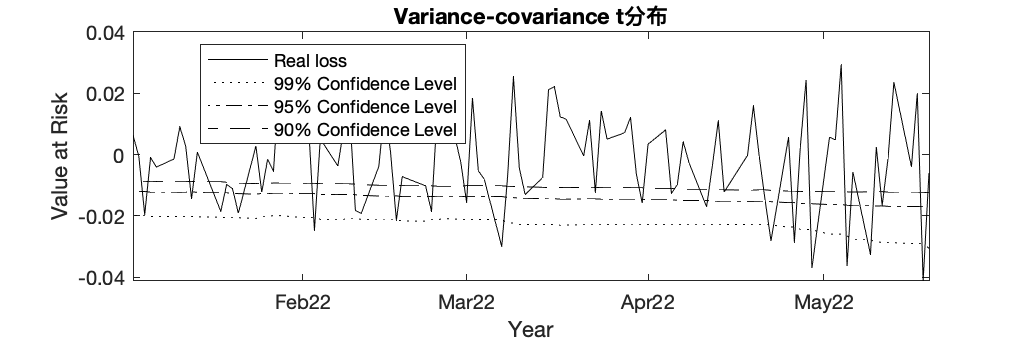

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,'Variance-covariance &');
line2latex(TableOutput(3,:),ftxt)
fclose(ftxt);
figureVaR(pVaR_t(:,FigureVaRIndex),logRet,TimeLine);
title('Variance-covariance t分布')

## GARCH t VaR

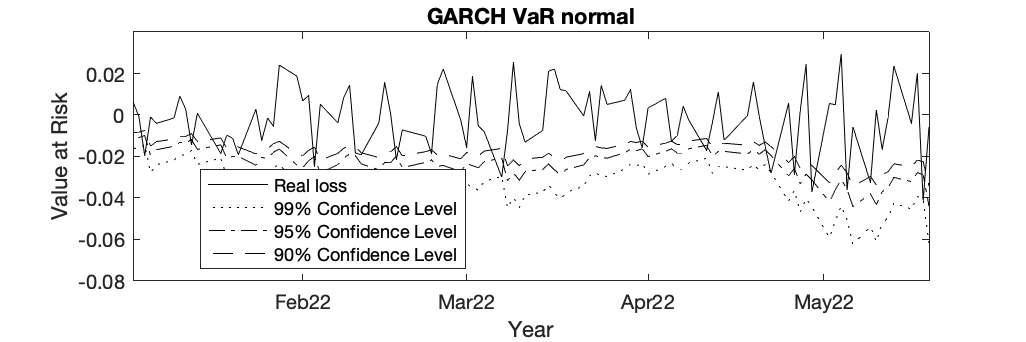

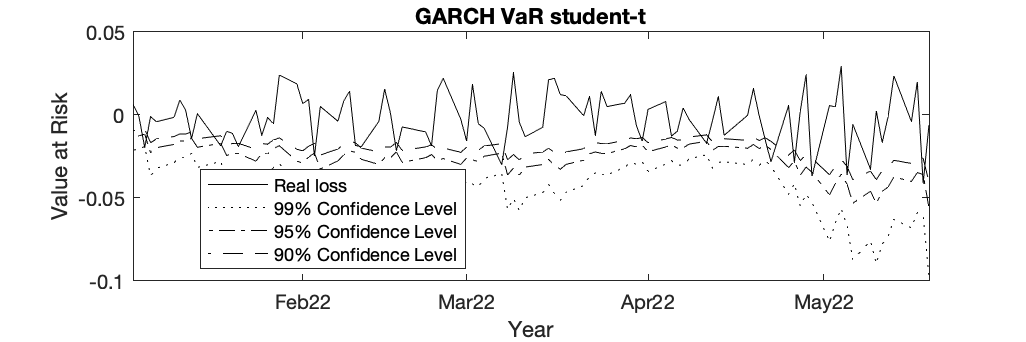

Model_Name='GARCH';
vf=database.vf_GARCH;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_t(3,:),ftxt)
fclose(ftxt);

## CPGARCH t VaR

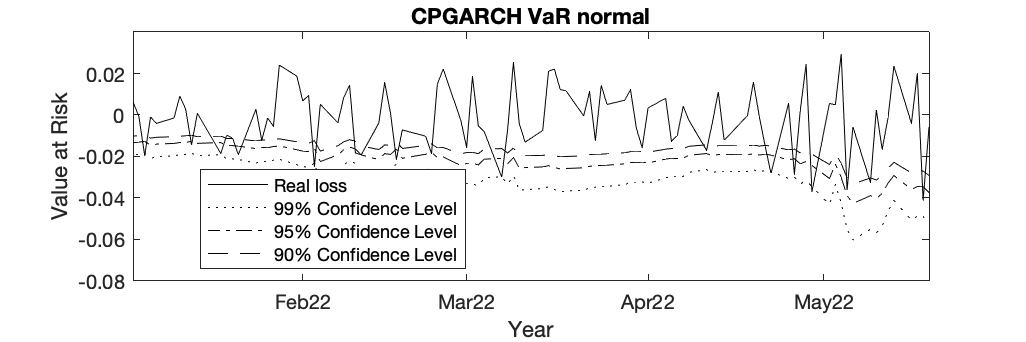

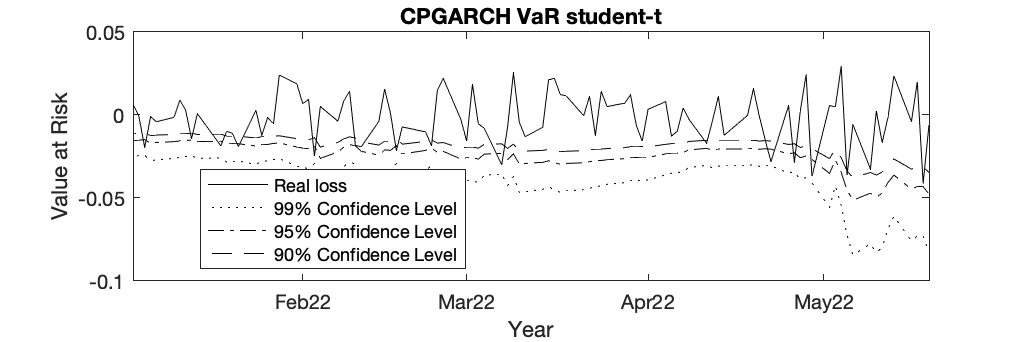

Model_Name='CPGARCH';
vf=database.vf_CPGARCH;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_t(3,:),ftxt)
fclose(ftxt);

## CPGARCHiteration t VaR

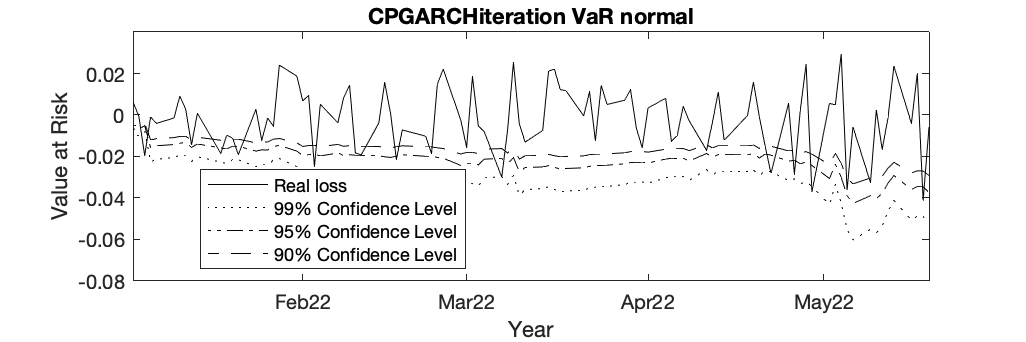

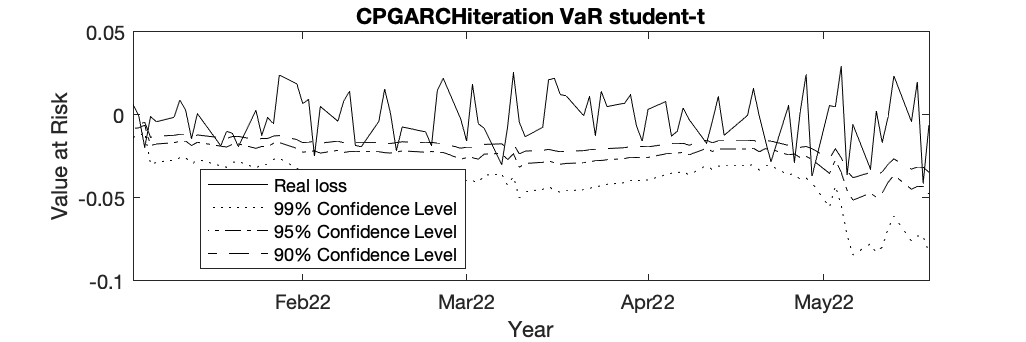

Model_Name='CPGARCHiteration';
vf=database.vf_CPGARCHiteration;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_t(3,:),ftxt)
fclose(ftxt);

## GJR t VaR

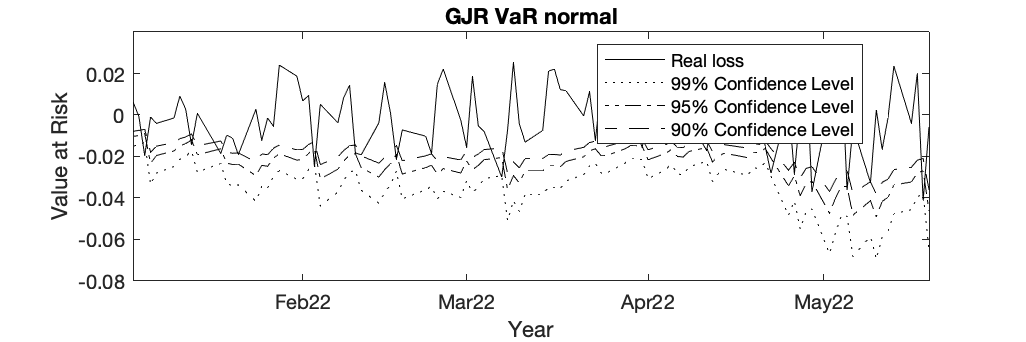

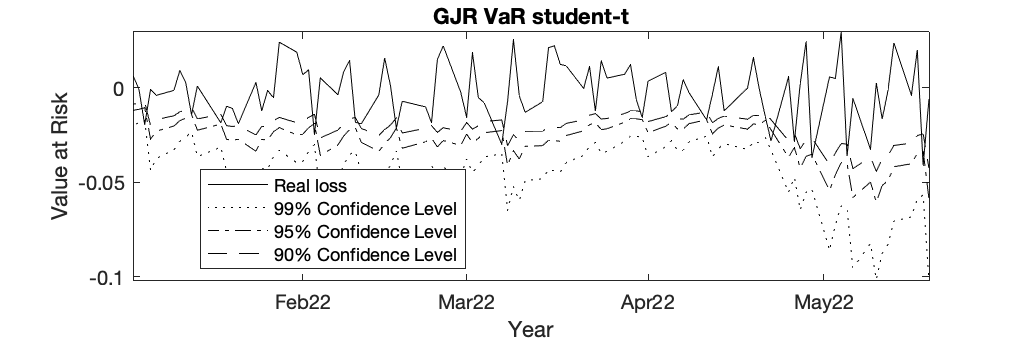

Model_Name='GJR';
vf=database.vf_GJR;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_t(3,:),ftxt)
fclose(ftxt);

## CPGJR t VaR

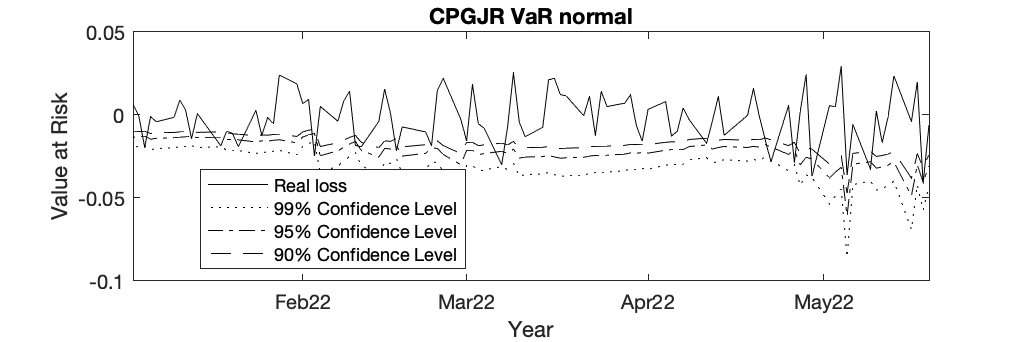

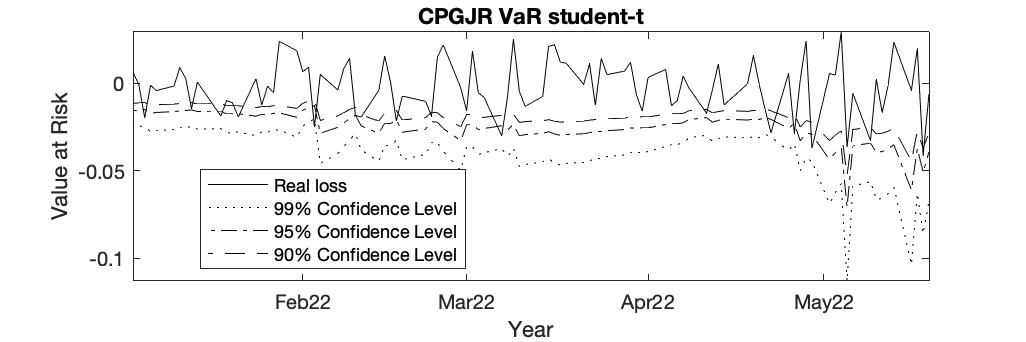

Model_Name='CPGJR';
vf=database.vf_CPGJR;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_t(3,:),ftxt)
fclose(ftxt);

## CPGJRiteration t VaR

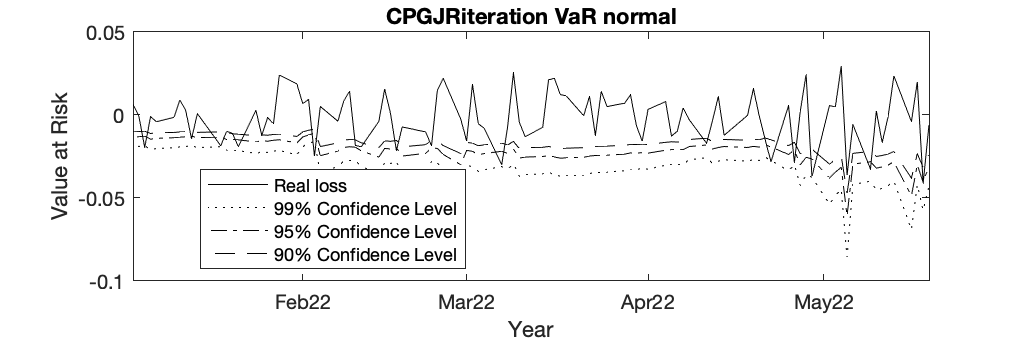

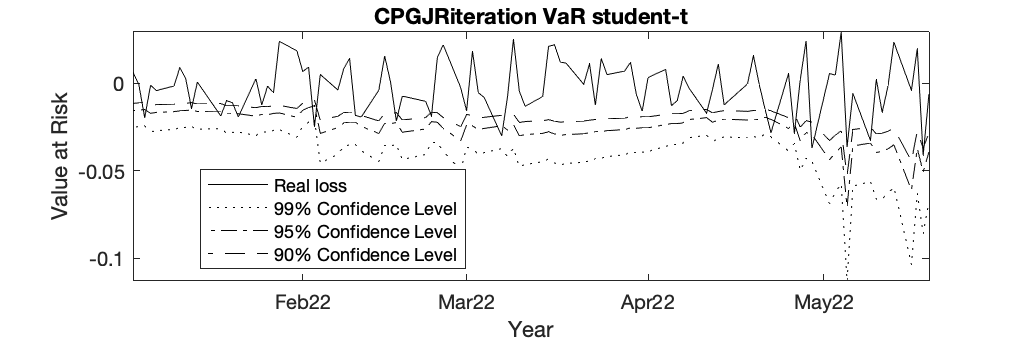

Model_Name='CPGJRiteration';
vf=database.vf_CPGJRiteration;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_t(3,:),ftxt)
fclose(ftxt);

## RSGARCH t VaR

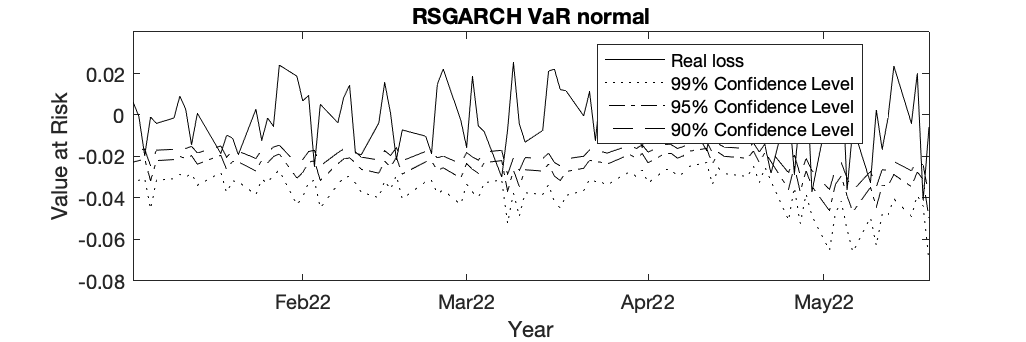

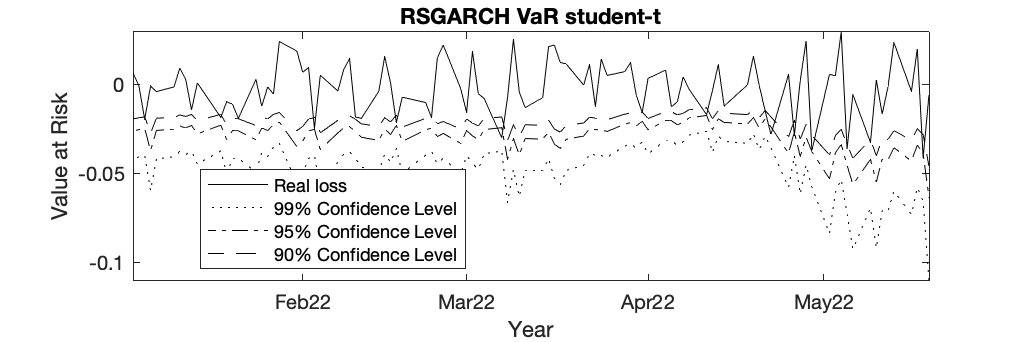

Model_Name='RSGARCH';
vf=database.vf_RSGARCH;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_t(3,:),ftxt)
fclose(ftxt);

## CPRSGARCH t VaR

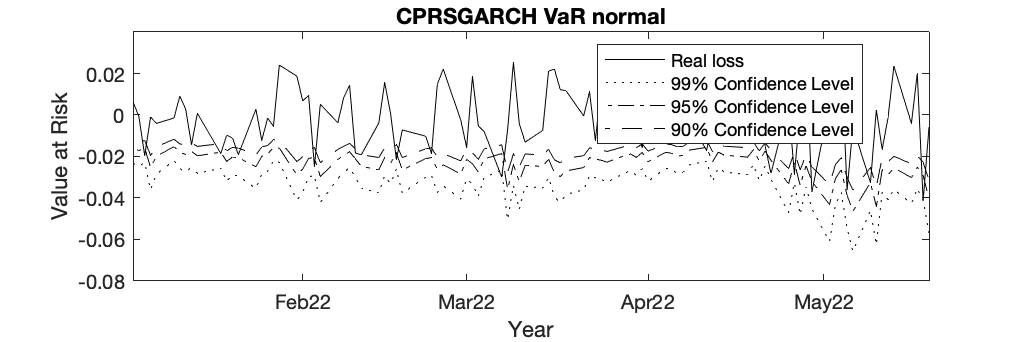

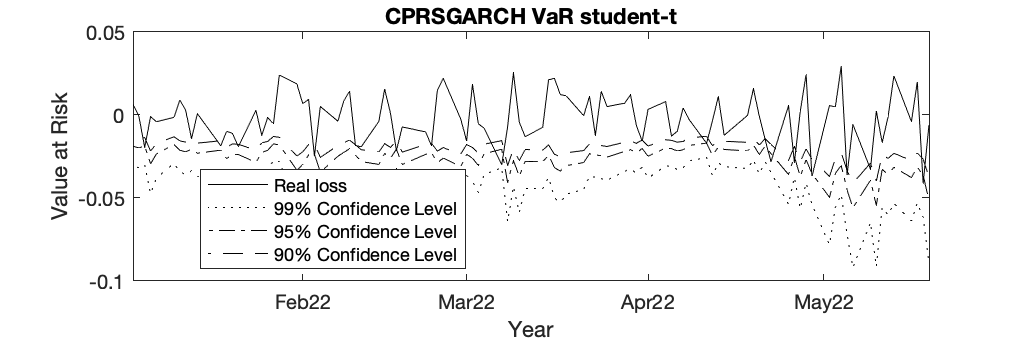

Model_Name='CPRSGARCH';
vf=database.vf_CPRSGARCH;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_t(3,:),ftxt)
fclose(ftxt);

## CPRSGARCHiteration t VaR

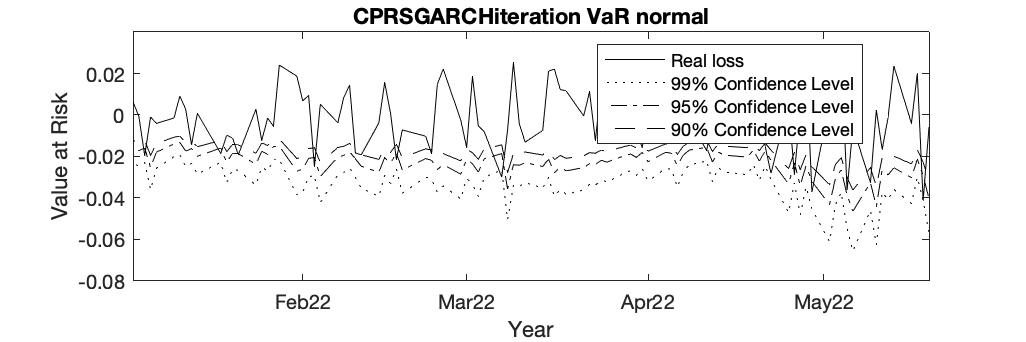

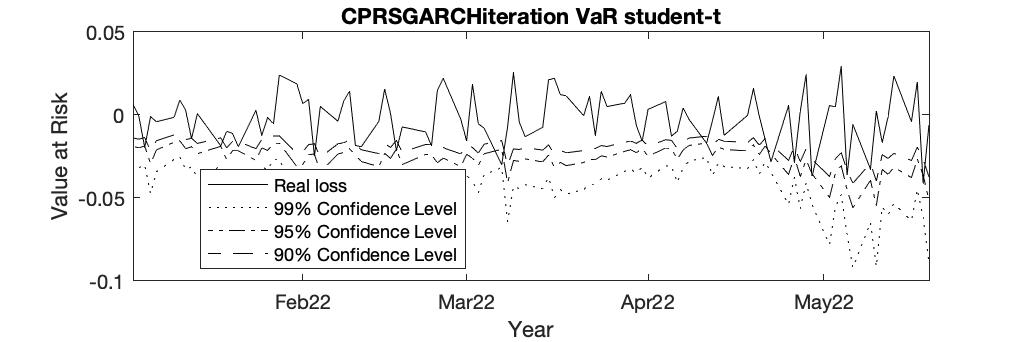

Model_Name='CPRSGARCHiteration';
vf=database.vf_CPRSGARCHiteration;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_t(3,:),ftxt)
fclose(ftxt);

## HAR tVaR

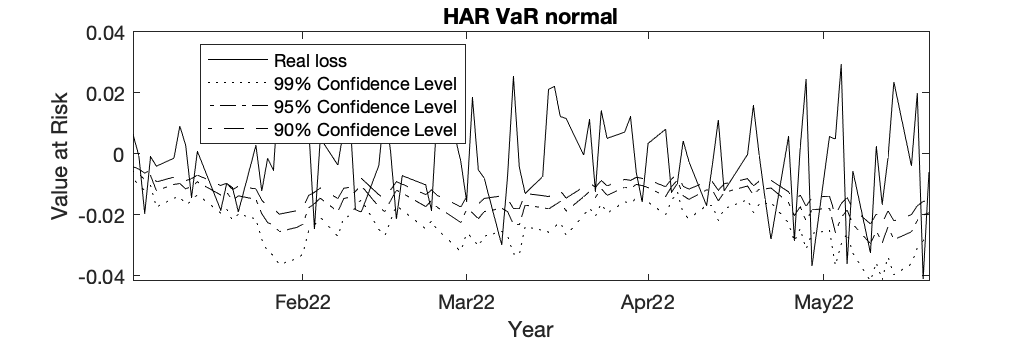

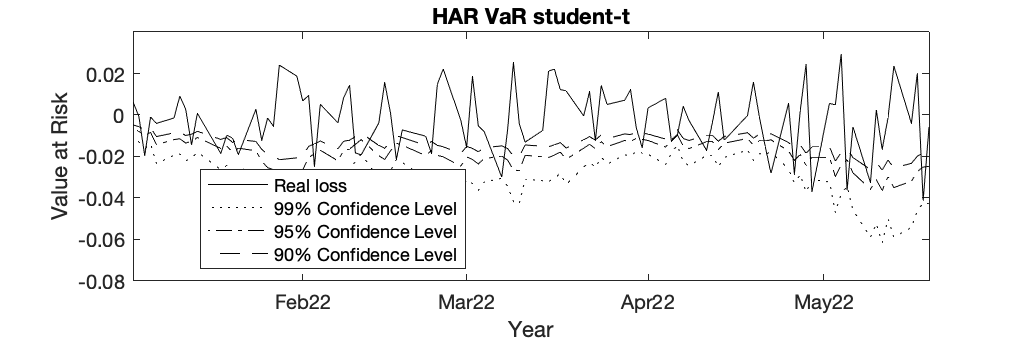

Model_Name='HAR';
vf=database.vf_HAR;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_t(3,:),ftxt)
fclose(ftxt);

## CPHAR t VaR

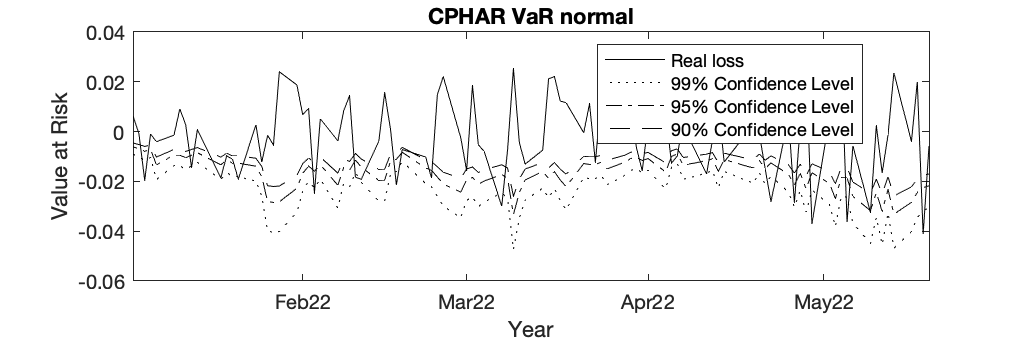

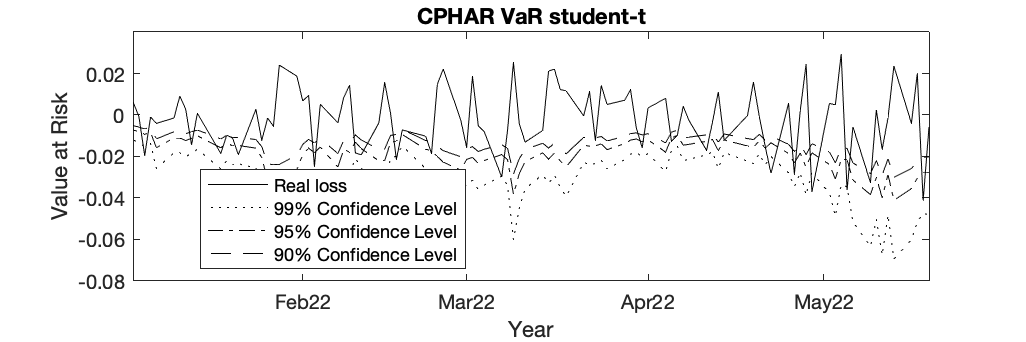

Model_Name='CPHAR';
vf=database.vf_CPHAR;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_t(3,:),ftxt)
fclose(ftxt);

## CPHARiteration t VaR

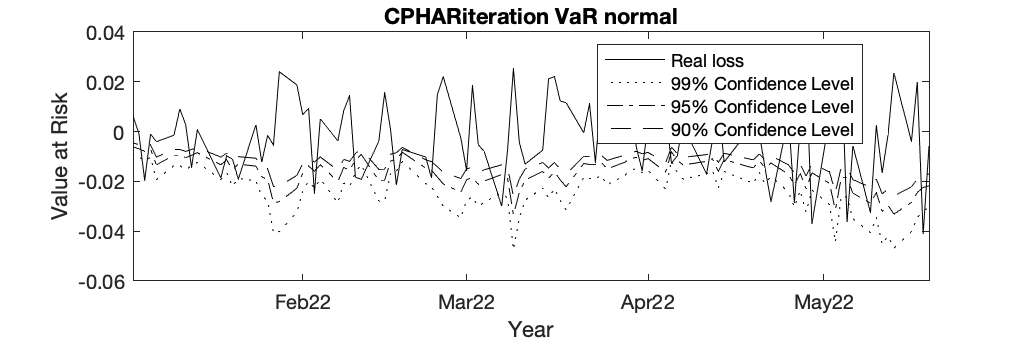

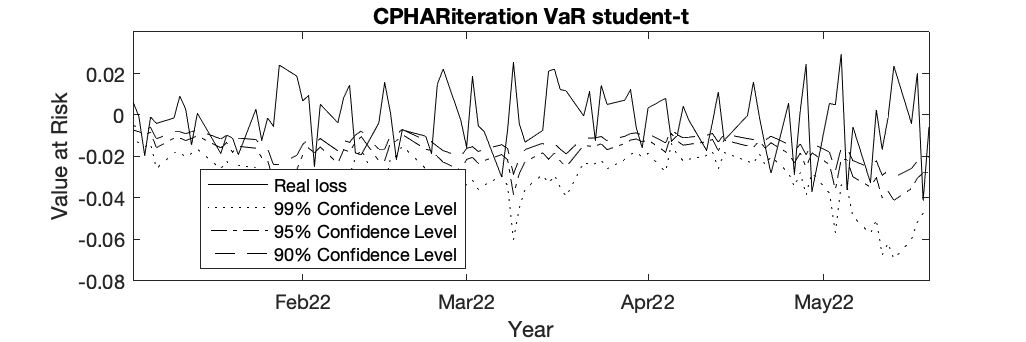

Model_Name='CPHARiteration';
vf=database.vf_CPHARiteration;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output.Table_t(3,:),ftxt)
fclose(ftxt);

% Closing the file
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\\hline \n');
fprintf(ftxt,'\\end{tabular}');
fclose(ftxt);

## Functions

function figureVaR(VaR,ret,TimeLine)
figure;
plot(TimeLine, ret, 'k' )
hold on 
plot(TimeLine, VaR(:,1), 'k:')
hold on 
plot(TimeLine, VaR(:,2),'k-.')
hold on 
plot(TimeLine, VaR(:,3),'k--')
xlim([TimeLine(1),TimeLine(end)])
xlabel('Year')
ylabel('Value at Risk')
% str1 = 'VaR Estimation by Volatility Structural Change Model with K=';
% str2 = num2str(K);
% MakeTitle = strcat(str1,str2);
% title(MakeTitle)
legend('Real loss','99% Confidence Level','95% Confidence Level','90% Confidence Level','Location', 'best')
dateaxis('x' , 12)
set(gcf,'Position',[500 500 900 300]);
end

LR statistic符合自由度为1的卡方分布

x:失败天数；

n：总天数；

p_star:null pypothesis failure rate；

LR = 2 * log( ( (1-x./n).^(n-x).*(x/n).^x) )...

        -2 * log( ( (1-p_star).^(n-x).*(p_star).^x) );

function line2latex(T,SaveTxtName)
    
    % Error detection and default parameters
    if nargin < 1, error('Not enough parameters.'); end
    
    % Parameters
    n_row = size(T,1);
    n_col = size(T,2);

    % Writing the data
    try
        for row = 1:n_row
            temp{1,n_col} = [];
            for col = 1:n_col
                value = T{row,col};
                if isstruct(value), error('Table must not contain structs.'), end
                while iscell(value), value = value{1,1}; end
                if isinf(value), value = '$\infty$'; end
                temp{1,col} = num2str(value);
                if value>chi2inv(0.99,1),temp{1,col} = ['\textbf{',num2str(value),'}$^{***}$'];
                elseif value>chi2inv(0.95,1),temp{1,col} = ['\textbf{',num2str(value),'}$^{**}$'];
                elseif value>chi2inv(0.9,1),temp{1,col} = ['\textbf{',num2str(value),'}$^{*}$'];
                else temp{1,col} = num2str(value);
                end
            end
            fprintf(SaveTxtName,'%s \\\\ \n', strjoin(temp, ' & '));
            clear temp;
        end
    catch
        error('Unknown error. Make sure that table only contains chars, strings or numeric values.');
    end
end

function LR  = LR_PF(x,n,p_star )
LR = 2 * log( ( ((1-x./n)/(1-p_star)).^(n-x) .* (x/n/p_star).^x) );
end

Report table and figure of VaR

function Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name)
VaR_normal = zeros(size(logRet,1),length(ConfidenceLevel));
VaR_t = zeros(size(logRet,1),length(ConfidenceLevel));
T=length(vf);
for i = 1 : T
    historic_return = D.Return(find(forecast_index,1)+i-251:find(forecast_index,1)+i-2);
    % innovation normal distributed
    VaR_normal(i, :) = norminv(ConfidenceLevel,mean(historic_return),sqrt(vf(i)));    
    % innovation student-t distributed
    fit_data=fitdist(historic_return,"tLocationScale");
    VaR_t(i, :) = tinv(ConfidenceLevel,fit_data.nu)*sqrt(vf(i))+mean(historic_return);
end
Table_normal=tableVaRPredict(VaR_normal,logRet,ConfidenceLevel);
figureVaR(VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])

Table_t=tableVaRPredict(VaR_t,logRet,ConfidenceLevel);
figureVaR(VaR_t(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR student-t'])

Output.Table_normal=Table_normal;
Output.Table_t=Table_t;
Output.VaR_normal=Table_normal;
Output.VaR_t=Table_t;

end

function table2latex(T)
    
    % Error detection and default parameters
    if nargin < 1, error('Not enough parameters.'); end
    if ~istable(T), error('Input must be a table.'); end
    
    % Parameters
    n_row = size(T,1);
    n_col = size(T,2);
    col_spec = [];
    for c = 1:n_col, col_spec = [col_spec 'l']; end
    col_names = strjoin(T.Properties.VariableNames, ' & ');
    row_names = T.Properties.RowNames;
    if ~isempty(row_names)
        col_spec = ['l' col_spec]; 
        col_names = ['& ' col_names];
    end
    
    % Writing header
    fprintf('\\begin{tabular}{%s}\n', col_spec);
    fprintf('%s \\\\ \n', col_names);
    fprintf('\\hline \n');
    
    % Writing the data
    try
        for row = 1:n_row
            temp{1,n_col} = [];
            for col = 1:n_col
                value = T{row,col};
                if isstruct(value), error('Table must not contain structs.'), end
                while iscell(value), value = value{1,1}; end
                if isinf(value), value = '$\infty$'; end
                temp{1,col} = num2str(value);
                if value>chi2inv(0.99,1),temp{1,col} = ['\textbf{',num2str(value),'}$^{***}$'];
                elseif value>chi2inv(0.95,1),temp{1,col} = ['\textbf{',num2str(value),'}$^{**}$'];
                elseif value>chi2inv(0.9,1),temp{1,col} = ['\textbf{',num2str(value),'}$^{*}$'];
                else temp{1,col} = num2str(value);
                end
            end
            if ~isempty(row_names)
                temp = [row_names{row}, temp];
            end
            fprintf('%s \\\\ \n', strjoin(temp, ' & '));
            clear temp;
        end
    catch
        error('Unknown error. Make sure that table only contains chars, strings or numeric values.');
    end
    
    % Closing the file
    fprintf('\\hline \n');
    fprintf('\\end{tabular}');
end

To generate table which reports Kupiec test of VaR estimate

function [TableOutput,ConfidenceLevel_Label]=tableVaRPredict(VaRPredict,logRet,ConfidenceLevel)
format short
switch nargin
    case 2
        ConfidenceLevel = 0.05;
end
outsampleSize=numel(logRet);
% make label of table
Confidence_Length=numel(ConfidenceLevel);
ConfidenceLevel_Label=cell(1,Confidence_Length);
ConfidenceLevel=reshape(ConfidenceLevel,Confidence_Length,1);
for i=1:Confidence_Length
    ConfidenceLevel_Label{1,i}=['CL',num2str(ConfidenceLevel(i))];
end
% Kupiec_Test=zeros(size(ConfidenceLevel));
% Kupiec_Test_Significance=zeros(size(ConfidenceLevel));
% Count_Failure=zeros(size(ConfidenceLevel));
% for i = 1:Confidence_Length
%     Count_Failure(i)=sum(VaRPredict(:,i)>logRet);
%     Kupiec_Test(i)=roundn(LR_PF(Count_Failure(i),outsampleSize,ConfidenceLevel(i)),-2);
%     Kupiec_Test_Significance(i)=chi2cdf(Kupiec_Test(i),1);
% end
% TableOutput=table([ConfidenceLevel,Count_Failure,Kupiec_Test,Kupiec_Test_Significance]', ...
%     'RowNames',{'Confidence level','Failures','Kupiec Test','Significance'});
TableOutput=zeros(3,length(ConfidenceLevel));
for i = 1:Confidence_Length
    TableOutput(1,i)=ConfidenceLevel(i);
    TableOutput(2,i)=sum(VaRPredict(:,i)>logRet);
    TableOutput(3,i)=roundn(LR_PF(TableOutput(2,i),outsampleSize,TableOutput(1,i)),-2);
    TableOutput(4,i)=chi2cdf(TableOutput(3,i),1);  
end
TableOutput=array2table(TableOutput,'RowNames',{'Confidence level','Failures','Kupiec Test','Significance'},'VariableNames',ConfidenceLevel_Label);
end